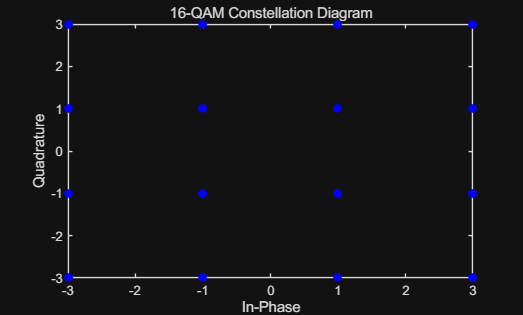

% Parameters
N = 128;        % Number of subcarriers per OFDM symbol
M = 1000;       % Number of OFDM symbols
SNR_dB = 0:5:30; % SNR range from 0 to 30 dB in steps of 5 dB

% Generate MN 16-QAM data
data = randi([0, 15], N, M); 
X = qammod(data, 16);

% Plot the 16-QAM constellation
figure;
plot(real(X), imag(X), 'bo', 'MarkerFaceColor', 'b');
title('16-QAM Constellation Diagram');
xlabel('In-Phase');
ylabel('Quadrature');

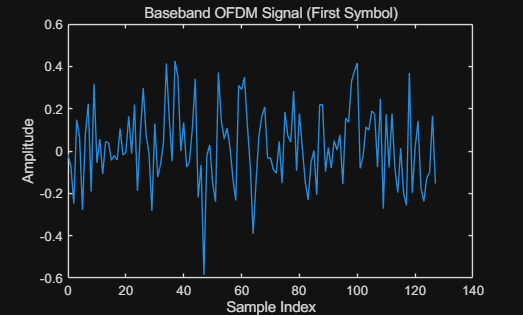


% Generate baseband OFDM signal using IFFT
ofdm_signal = ifft(X, N);

% Time axis for plotting (assuming unit sampling interval)
t = (0:N-1);

% Plot the baseband OFDM signal for the first symbol
figure;
plot(t, real(ofdm_signal(:,1)));
title('Baseband OFDM Signal (First Symbol)');
xlabel('Sample Index');
ylabel('Amplitude');

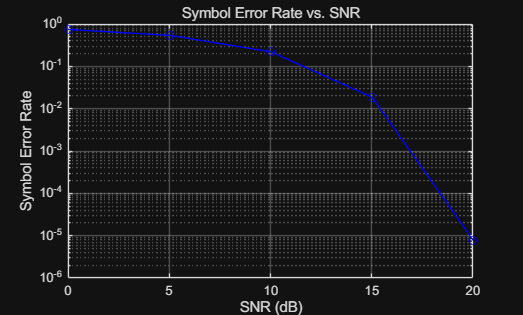


% Initialize symbol error rate array
ser = zeros(length(SNR_dB), 1);

% Loop over different SNR values
for idx = 1:length(SNR_dB)
    % Add AWGN noise to the transmitted signal
    rx_signal = awgn(ofdm_signal, SNR_dB(idx), 'measured');

    % Recover the signal using FFT
    Y = fft(rx_signal, N);

    % Demodulate the received symbols
    data_hat = qamdemod(Y, 16);

    % Calculate symbol errors
    num_errors = sum(sum(data_hat ~= data));
    total_symbols = N * M;
    ser(idx) = num_errors / total_symbols;
end

% Plot Symbol Error Rate vs. SNR
figure;
semilogy(SNR_dB, ser, 'b-o');
title('Symbol Error Rate vs. SNR');
xlabel('SNR (dB)');
ylabel('Symbol Error Rate');
grid on;